# Load dataset

clear all;
close all;
clc;
dim_cal = 200

dim_cal = 200

txt = 'LR1'

txt = 'LR1'

load(sprintf('datasets/%s_input_randomfield_cal%i', txt, dim_cal));
addpath('functions/');
her.txt = txt; %dataset identification

## Define infogram and Geo3 properties

her.lag_dist = 2.0; % DEFINE the class size (lag width in meters if the input x,y is given in meters)
her.binwidth = 0.20; % DEFINE delta z binwidth
her.binwidth_z = her.binwidth; % DEFINE binwidth for the z PMFs
her.n_neighbor = 12; % DEFINE the maximum number of neighbord to be considered in the interpolation and AND_OR optimization (n_neighbor-1) (min 2, max dim_cal)
%to be used in Geo3 part (no need to run Geo1 and Geo2 parts when you change it)
her.aggregation_type = 'andor';  %DEFINE the aggregation method
z_thresh = NaN; %DEFINE z threshold for obtaining the probability map
%(probability of exceeding z_thresh threshold).
%NaN if no one is desired

## Geo1: Spatial Characterization

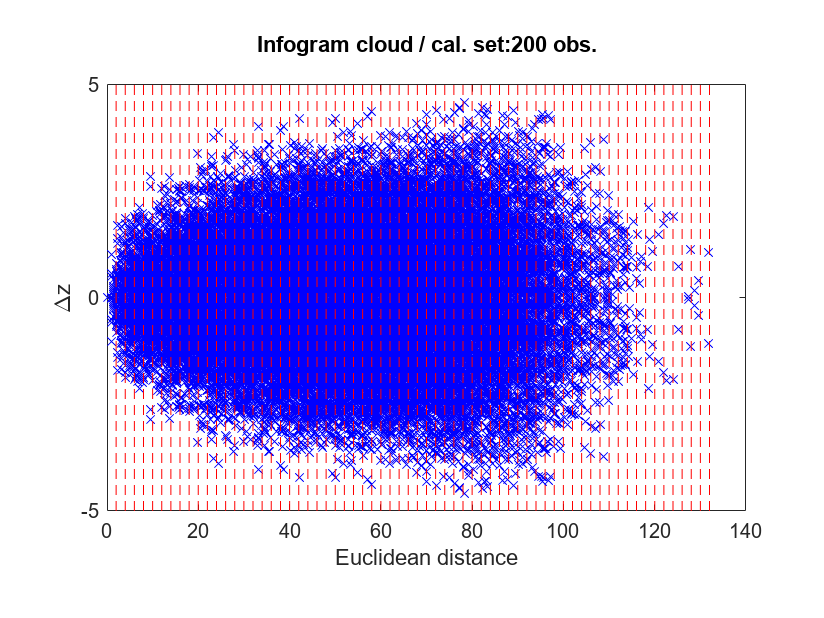

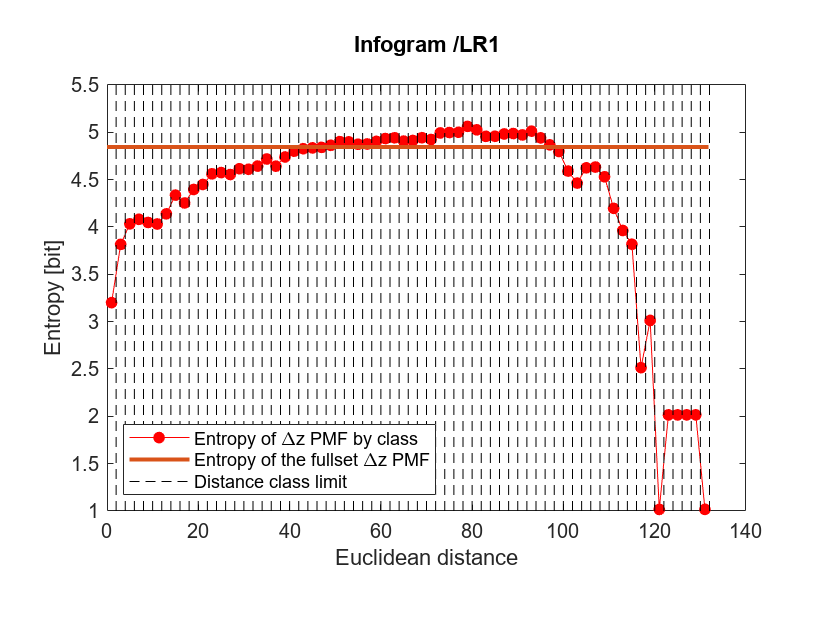

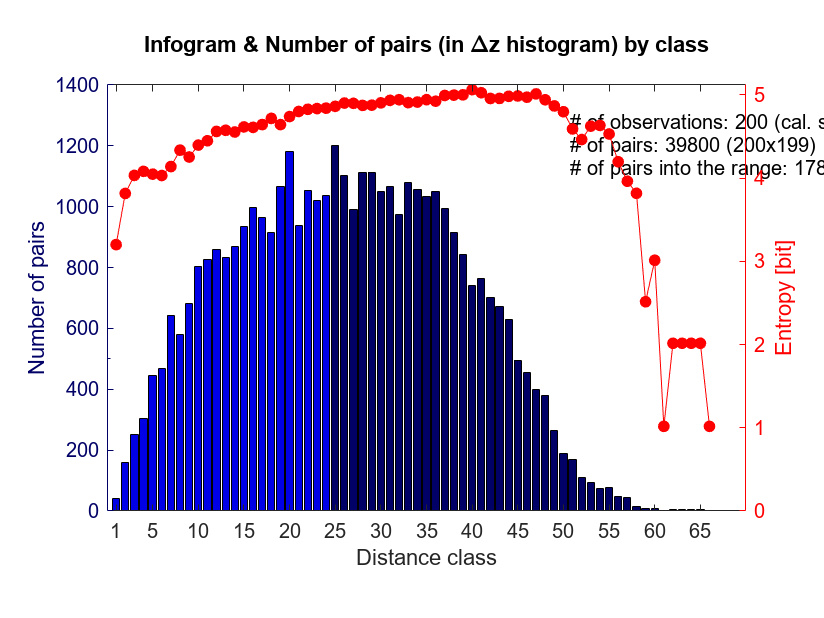

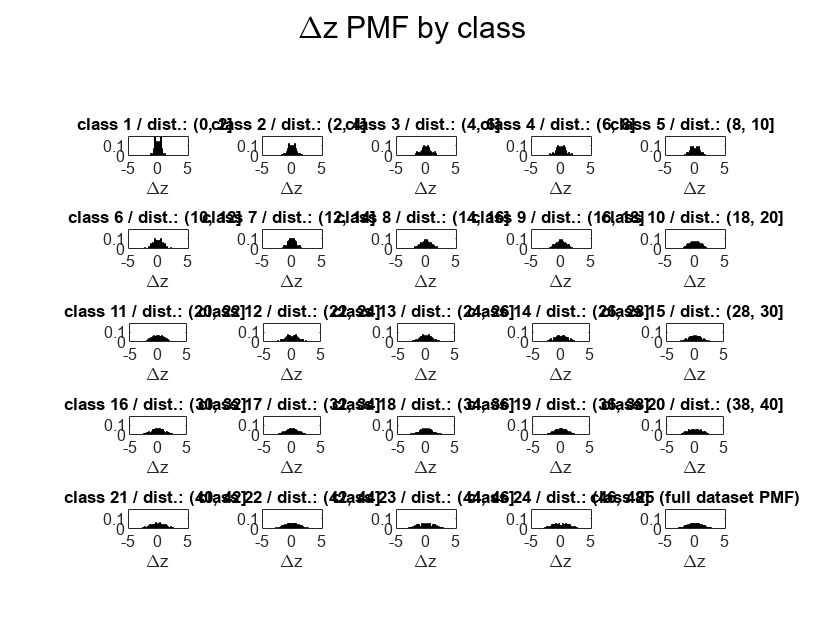

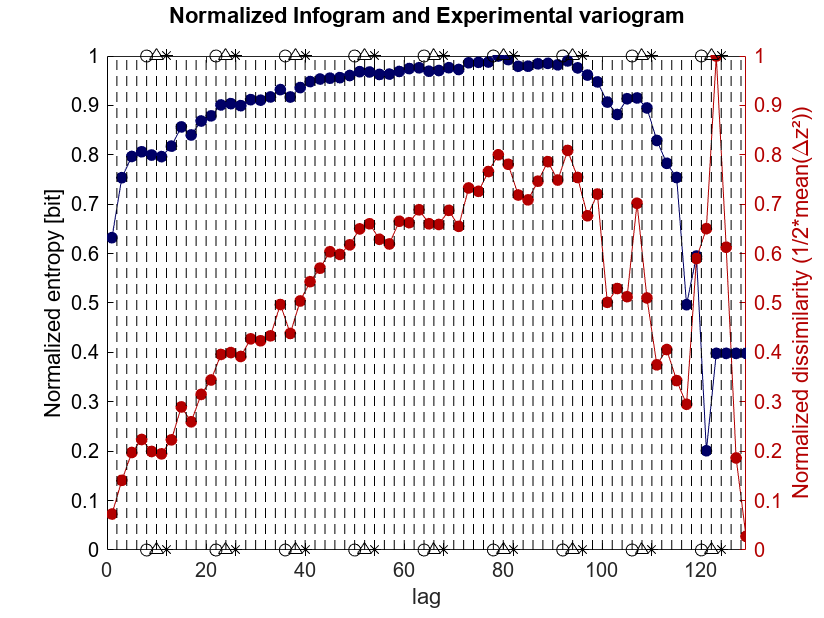

her = f_her_infogram(x_cal, y_cal, z_cal, her);

% plot Infogram cloud, Infogram & Number of pairs, Histogram of delta_z classes, normalized infogram + variogram
f_plot_infogram(her);

## Geo2: Weight optimization

(leave-one-out cross validation on calibration dataset)

her = f_her_weight(x_cal, y_cal, z_cal, her);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      25    4.242201e+00    0.000e+00    2.466e-01
    1      50    4.029188e+00    0.000e+00    8.518e+00    1.188e-01
    2      75    3.937639e+00    0.000e+00    8.915e+00    6.374e-02
    3     100    3.841720e+00    0.000e+00    1.078e+01    9.898e-02
    4     125    3.830308e+00    0.000e+00    1.471e+00    3.318e-02
    5     150    3.818545e+00    0.000e+00    1.807e+00    5.574e-02
    6     175    3.797714e+00    0.000e+00    2.570e+00    1.165e-01
    7     200    3.780074e+00    0.000e+00    5.245e-01    1.251e-01
    8     225    3.767032e+00    0.000e+00    9.529e-01    1.086e-01
    9     250    3.770640e+00    0.000e+00    4.169e+00    3.337e-02
   10     275    3.767657e+00    0.000e+00    1.040e+00    7.500e-02
   11     300    3.767055e+00    0.000e+00    7.560e-02    7.524e-02
   12     325    3.767484e+00    0.000e+00    8

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      26    3.656882e+00    0.000e+00    2.735e-01
    1      56    3.333513e+00    1.719e-03    3.379e-01    1.190e-01
    2      82    3.321473e+00    1.828e-02    4.039e+00    1.142e-01
    3     108    3.316343e+00    1.426e-02    4.947e+00    3.387e-02
    4     134    3.318489e+00    5.398e-03    4.399e+00    3.322e-02
    5     160    3.322103e+00    2.513e-03    3.951e+00    1.256e-02
    6     187    3.325003e+00    2.491e-05    3.883e+00    9.587e-03
    7     213    3.329888e+00    0.000e+00    4.058e+00    1.466e-02
    8     239    3.330274e+00    0.000e+00    4.309e+00    4.447e-03
    9     265    3.330177e+00    0.000e+00    6.030e-01    1.136e-03
   10     291    3.330045e+00    0.000e+00    6.743e-02    1.916e-03
   11     317    3.312580e+00    0.000e+00    1.257e-01    3.665e-01
   12     343    3.309656e+00    0.000e+00    3

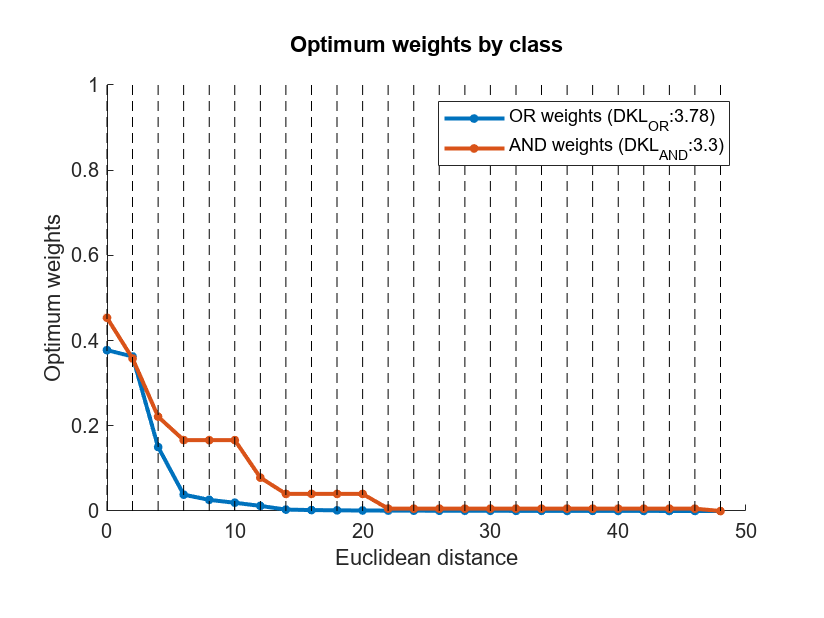

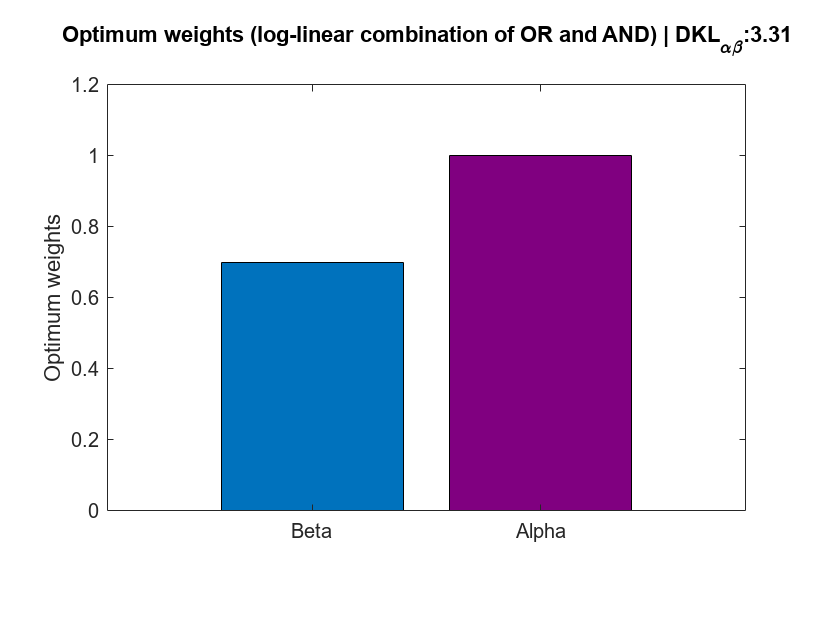


% plot optimum weight
f_plot_weights(her);

## Geo3: z PMF prediction

%GRID for ploting results
[x_target_grid,y_target_grid] = meshgrid(1:100, 1:100); %DEFINE a grid for predicting and ploting results
x_target_grid = round(x_target_grid,2);
y_target_grid = round(y_target_grid,2);
x_target = x_target_grid(:);
y_target = y_target_grid(:);

%Predict GRID
[pmf_pred_nn, target_idx_zero_neigh_pred] = f_her_predict(x_cal, y_cal,z_cal, x_target, y_target, her);

% %Predict validation set (for performance analysis, if your validation set does not match with the grid)
% % x and y here could be a column vector
% [pmf_pred_nn, target_idx_zero_neigh_pred] = f_her_predict(x_cal, y_cal,z_cal, x, y, her);

## Extract PMF statistics

extract mean, median, mode, probability and plot

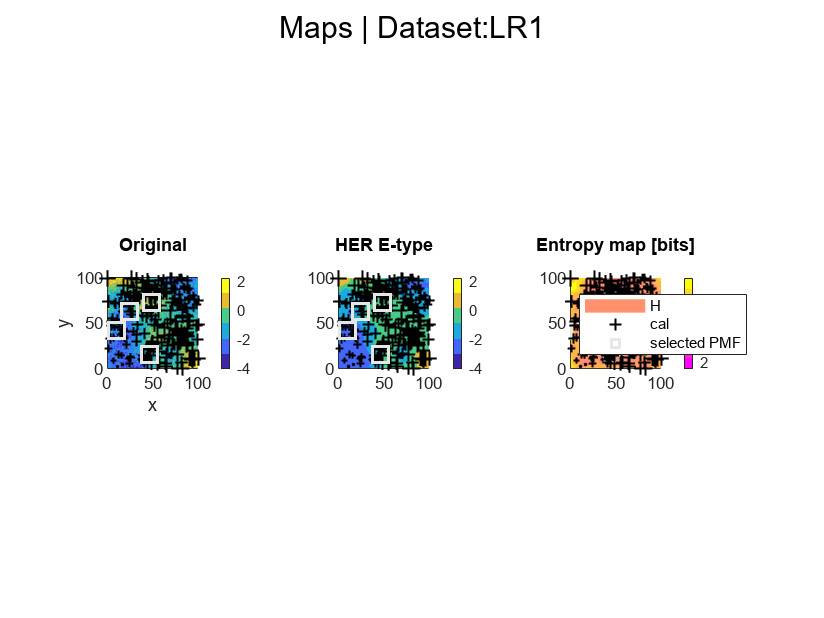

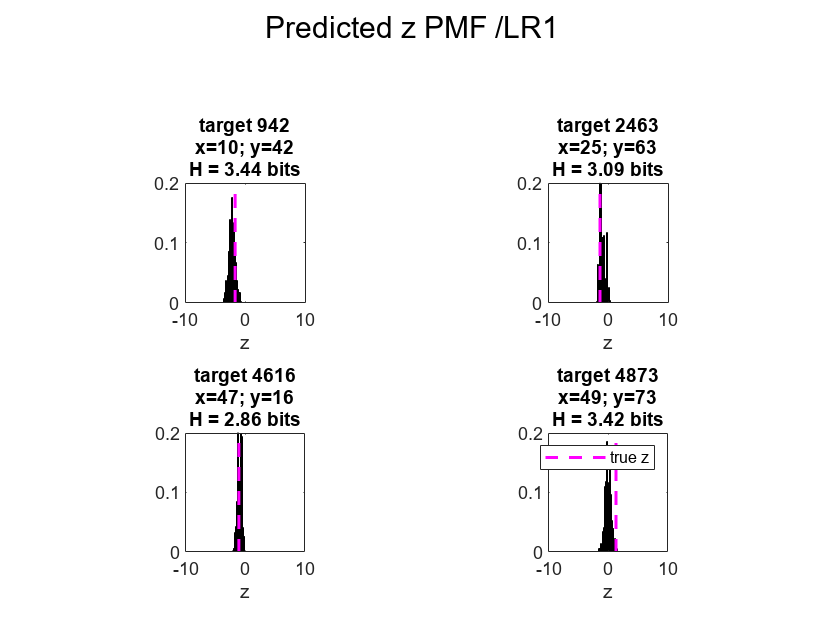

% GRID: plot maps and predicted PMFs
[z_target_entropy_pred_GRID_plot, z_target_mean_pred_GRID_plot, z_target_median_pred_GRID_plot, z_target_mode_pred_GRID_plot, z_target_probability_pred_GRID_plot] = f_extract_pmf_statistics(x_target_grid, y_target_grid, pmf_pred_nn, her.bin_centers_edges_z, z_thresh);
x_pmf = [10, 25, 47, 49]; y_pmf = [42, 63, 16, 73]; %coordinates to plot predicted PMF
f_plot_prediction(z_target_mean_pred_GRID_plot, z_target_entropy_pred_GRID_plot, pmf_pred_nn, x_target, y_target, x_target_grid, y_target_grid, x, y, z, idx_cal, her, x_pmf, y_pmf,'Y');

% f_plot_probabilitymap(z_target_probability_pred_GRID_plot, z_thresh, txt, x_target_grid, y_target_grid, x, y, z, idx_cal);

## Calculate performance metrics

Root mean square error (RMSE) Mean Error (ME) Mean Absolute Error (MAE) L1 norm, robust parameter estimator Nash-Sutcliffe model efficiency (r2, coefficient of determination)

z_target_pred_ = z_target_mean_pred_GRID_plot;
pmf_ = pmf_pred_nn;

% performance validation set
[perf.error_sign_val, perf.RMSE_val, perf.ME_val, perf.MAE_val, perf.NSE_val] = f_performance_det(z_target_pred_(idx_val),z(idx_val));
% scoring rule - DKL
PMF_true_val = ones(1,length(idx_val));
PMF_simulated_val = pmf_(idx_val);
perf.DKL_score_mean_val = f_performance_prob(z_val', PMF_simulated_val, PMF_true_val, her.edges_z);
perf.correl_val = corr(z_val, (z_target_pred_(idx_val) - z_val));

## performance test set

[perf.error_sign_test, perf.RMSE_test, perf.ME_test, perf.MAE_test, perf.NSE_test] = f_performance_det(z_target_pred_(idx_test),z(idx_test));
% scoring rule - DKL
PMF_true_test = ones(1,length(idx_test));
PMF_simulated_test = pmf_(idx_test);
perf.DKL_score_mean_test = f_performance_prob(z_test', PMF_simulated_test, PMF_true_test, her.edges_z);
perf.correl_test = corr(z_test, (z_target_pred_(idx_test) - z_test));

## clear

%Geo3
%Geo3
clear contamin_pred_ PMF_simulated_val PMF_true_val contamin_ pmf_ h1 h2 i ...
    idx_ ncols nrows z_predicted_ z_predicted_sorted_ z_true_sorted_

save(sprintf('HER_E02_lag%s_bw%s_nn%s_%s_dataset_%s.mat', num2str(round(her.lag_dist,2)), num2str(round(her.binwidth,4)), num2str(round(her.n_neighbor,0)),her.aggregation_type, her.txt));